# EGB242 Week 7 In Class Challenge

clear all, close all, clc

% NOTE: We have chosen to look at the signal first as this allows us to
% find the frequency range that the filters were made for.

## 1) Load sound file and observe spectrum

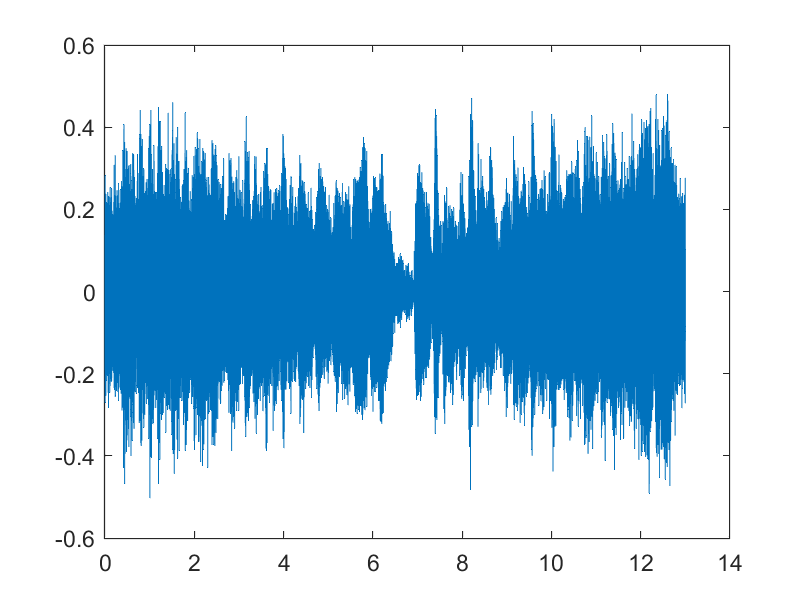

% Load sound file
[audio,fs] = audioread("AudioNoisy.wav");
% sound(audio, fs)

% Find spectrum as it's easier to see what's happening in the frequency
% domain, especially when considering filters
Ts = 1 / fs;
samples = length(audio);
Audio = fft(audio);
f = linspace(-fs/2, fs/2, samples + 1); f(end) = [];
t = linspace(0, samples / fs, samples + 1); t(end) = [];

figure, plot(t, audio);

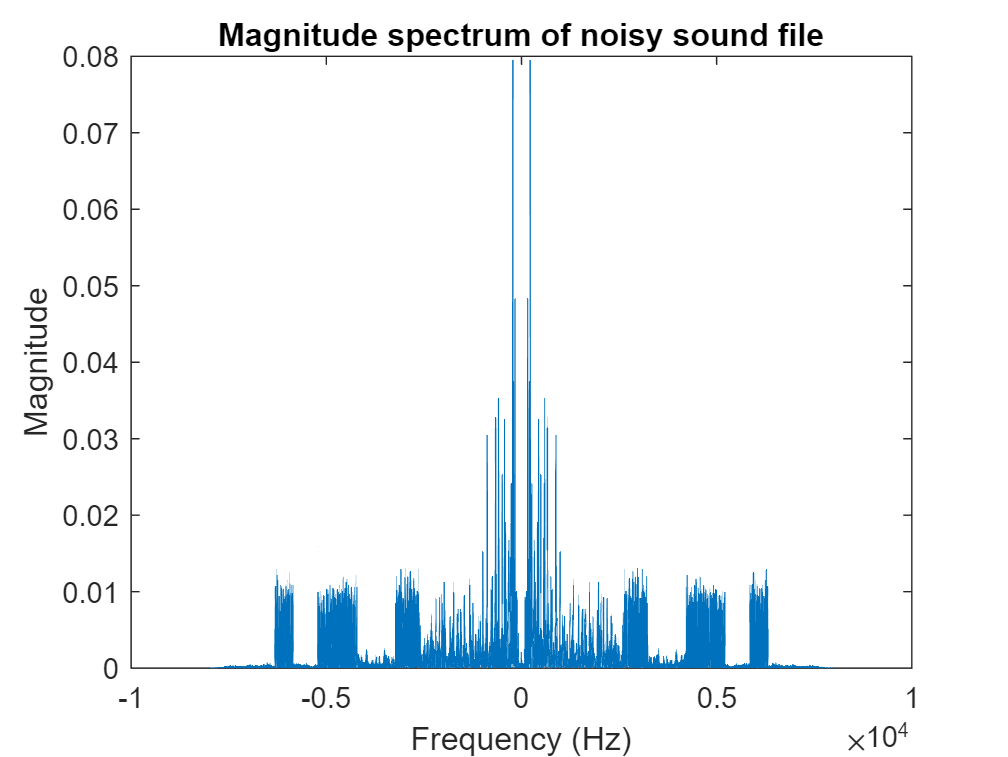


% Plot magnitude spectrum to look at what the filter is going to have to do
figure(1), clf, plot(f, abs(fftshift(Audio)) * Ts) % <-------------  Time in class to attempt
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('Magnitude spectrum of noisy sound file');

## 2) Identify filters

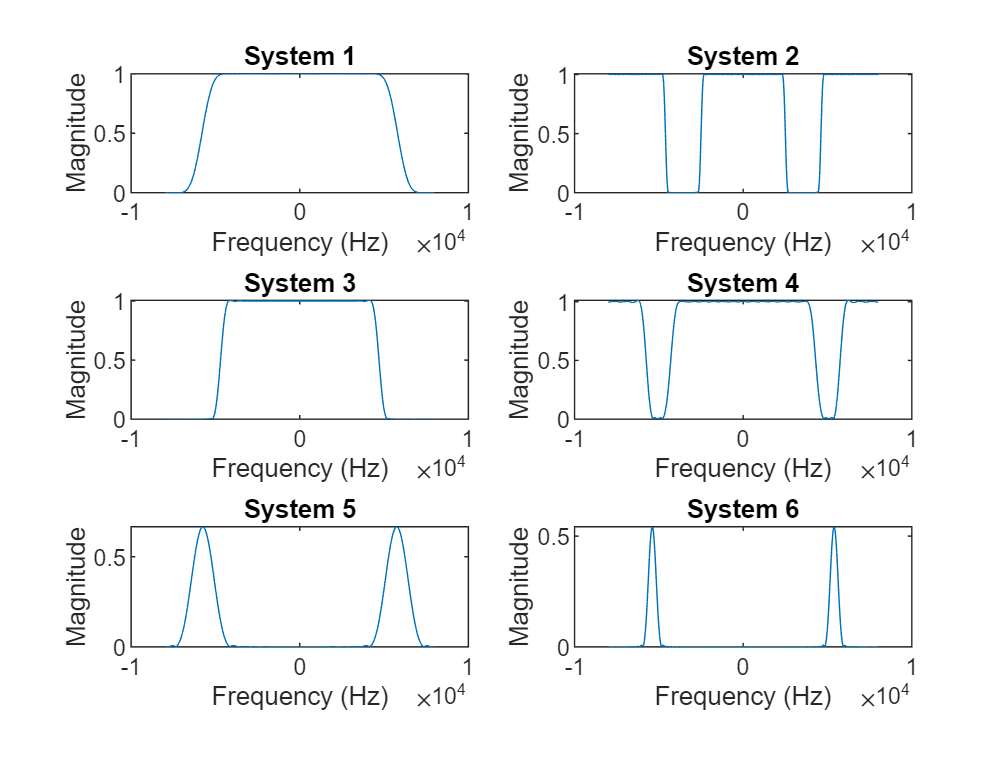

% Apply impulse and observe spectrum for each filter, create impulse of 50 pts long
imp = [1 / Ts, zeros(1, samples - 1)]; % <------------- Time in class to attempt

% NOTE: We use an impulse of height 1 because the fourier transform of an 
% impulse of amplitude 1 is 1 for every frequency. Looking at the
% definition for the output of an LTI system, in the frequency domain it
% looks like this:
% Y(f) = H(f) * X(f)
% If we input an impulse then X(f) is just a multiply by 1 so the output
% becomes:
% Y(f) = H(f)
% and therefore, we can view the exact behaviour of the system, also called
% the impulse response of the system. This is the main reason the behaviour
% of an LTI system is called the impulse response, its literally the
% response of the system to an impulse and shows exactly what is happening
% at every frequency

% System 1
h1 = System1(imp); 
h1 = h1(1:samples);
H1 = fftshift(fft(h1)) * Ts;

% System 2
h2 = System2(imp); 
h2 = h2(1:samples);
H2 = fftshift(fft(h2)) * Ts;

% System 3
h3 = System3(imp); 
h3 = h3(1:samples);
H3 = fftshift(fft(h3)) * Ts;

% System 4
h4 = System4(imp); 
h4 = h4(1:samples);
H4 = fftshift(fft(h4)) * Ts;

% System 5
h5 = System5(imp); 
h5 = h5(1:samples);
H5 = fftshift(fft(h5)) * Ts;

% System 6
h6 = System6(imp); 
h6 = h6(1:samples);
H6 = fftshift(fft(h6)) * Ts;

figure(2), clf
subplot(3,2,1), plot(f, abs(H1))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 1')

subplot(3,2,2), plot(f, abs(H2))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 2')

subplot(3,2,3), plot(f, abs(H3))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 3')

subplot(3,2,4), plot(f, abs(H4))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 4')

subplot(3,2,5), plot(f, abs(H5))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 5')

subplot(3,2,6), plot(f, abs(H6))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('System 6')

## 3) Apply noisy sound file through necessary Systems

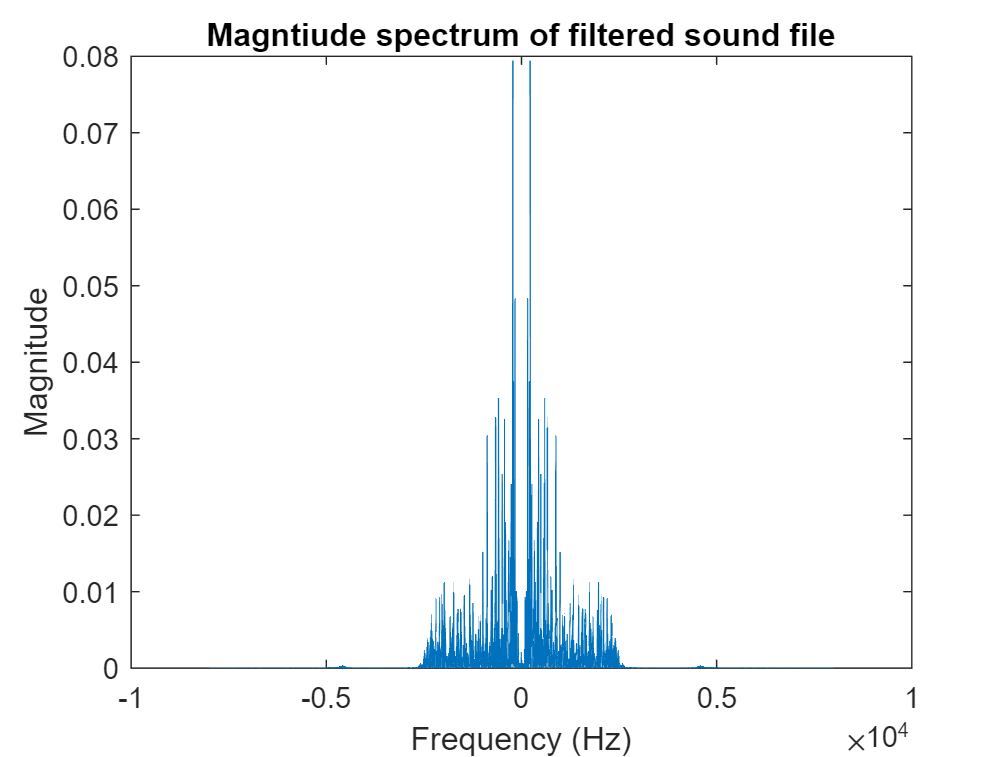

% Filter through system
clean1 = System2(audio);
clean2 = System3(clean1);
clean3 = System4(clean2);
clean = clean3(1:samples);

% observe spectrum
Clean = fftshift(fft(clean)) * Ts;

figure(3), clf
plot(f, abs(Clean))
xlabel('Frequency (Hz)'), ylabel('Magnitude')
title('Magntiude spectrum of filtered sound file')


% sound(clean3, fs)